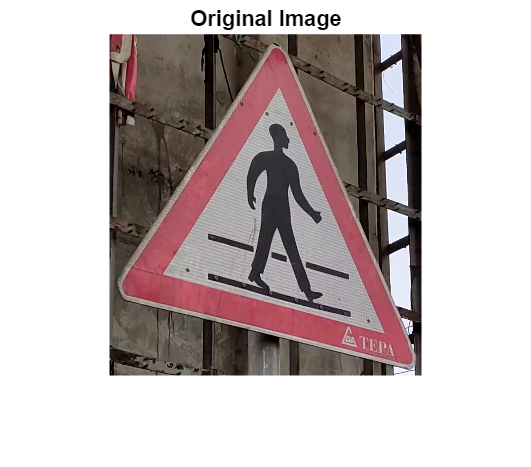

% Ask user to select an image
[filename, filepath] = uigetfile({'*.jpg;*.png', 'Image files (*.jpg, *.png)'}, 'Select an image');
if isequal(filename, 0) || isequal(filepath, 0)
    disp('No image selected. Exiting.');
    return;
end

% Read the selected image
imagePath = fullfile(filepath, filename);
inputImage = imread(imagePath);

% Display the original image
figure;
imshow(inputImage);
title('Original Image');

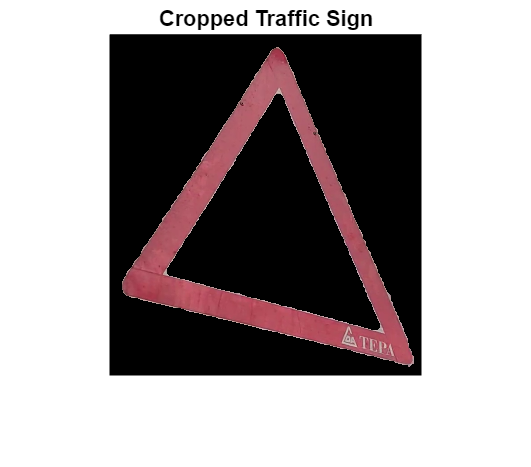


% Convert the image to the LAB color space
labImage = rgb2lab(inputImage);

% Extract the "a" channel which represents color differences
aChannel = labImage(:, :, 2);

% Thresholding to segment potential traffic sign regions
binaryImage = aChannel > 10; % Adjust threshold as needed

% Remove small noise regions
binaryImage = bwareaopen(binaryImage, 200);

% Perform morphological operations to enhance the regions
se = strel('disk', 5);
binaryImage = imclose(binaryImage, se);

% Identify and label connected components
cc = bwconncomp(binaryImage);
labeledImage = labelmatrix(cc);

% Calculate the area of each connected component
area = regionprops(cc, 'Area');
areaArray = [area.Area];

% Find the largest connected component (assumed to be the traffic sign)
[~, idx] = max(areaArray);

% Create a mask of the detected traffic sign
trafficSignMask = labeledImage == idx;

% Crop the original image using the mask
croppedTrafficSign = bsxfun(@times, inputImage, cast(trafficSignMask, 'like', inputImage));

% Display the cropped traffic sign
figure;
imshow(croppedTrafficSign);
title('Cropped Traffic Sign');